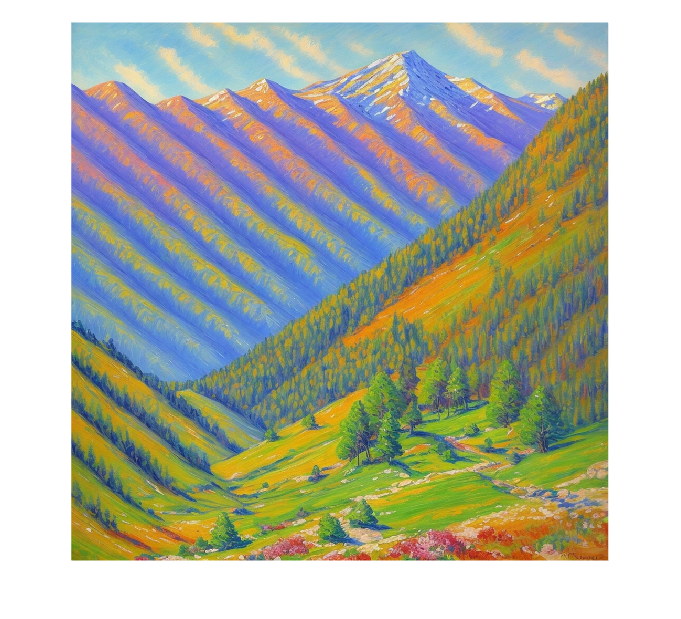

image = double(imread("C:\Users\gridd\OneDrive\Рабочий стол\ITMO\fourier_labs\Lab6\image\part-1\15.png"))/255; % read image with conversion to double from 0 to 1.
imshow(image)

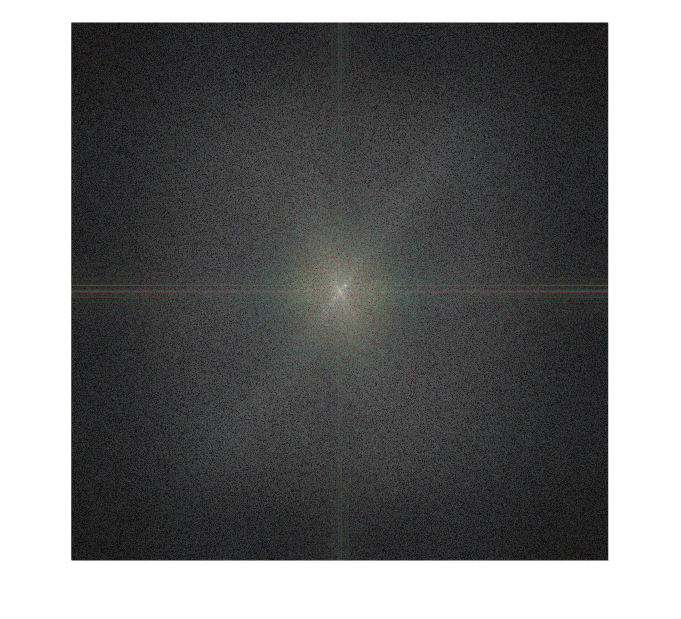

image_fourier = fftshift(fft2(image));  % calc Fourier transform on image

% divide fourier image into module and arg with abs & angle
module = log(1+abs(image_fourier)); 
module = (module-min(module(:)))/(max(module(:))-min(module(:)));
arg = angle(image_fourier); 
imshow(module)

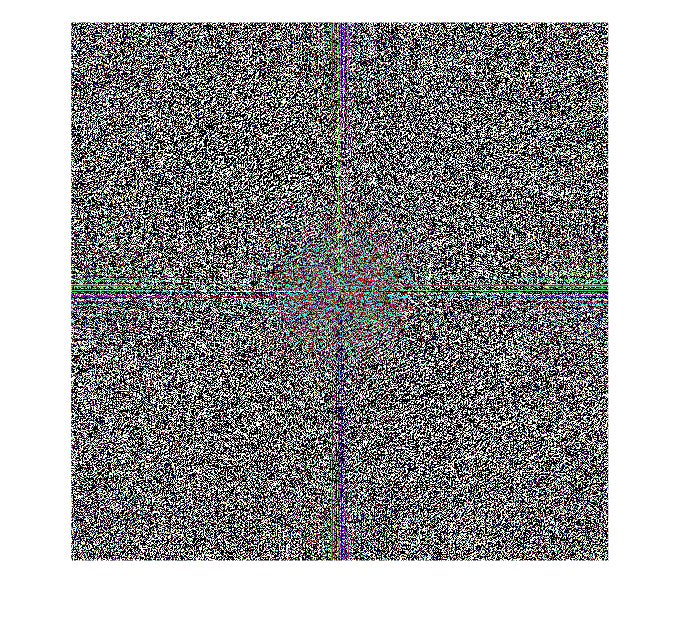


imshow(arg)

imwrite(module,"C:\Users\gridd\OneDrive\Рабочий стол\ITMO\fourier_labs\Lab6\image\part-1\fourier_orig_version.png"); % save the original Fourier image.
dir = "C:\Users\gridd\OneDrive\Рабочий стол\ITMO\fourier_labs\Lab6\image\part-1\"

dir = "C:\Users\gridd\OneDrive\Рабочий стол\ITMO\fourier_labs\Lab6\image\part-1\"

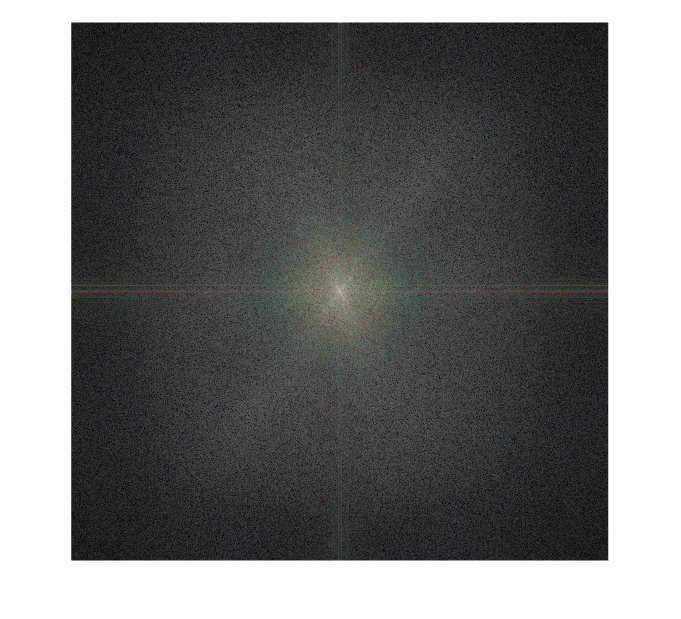

new_image_fourier = double(imread(dir + "img_fourier_filtered_v1.png"))/255; % read filtered fourier image and convert to double [0,1]
imshow(new_image_fourier)

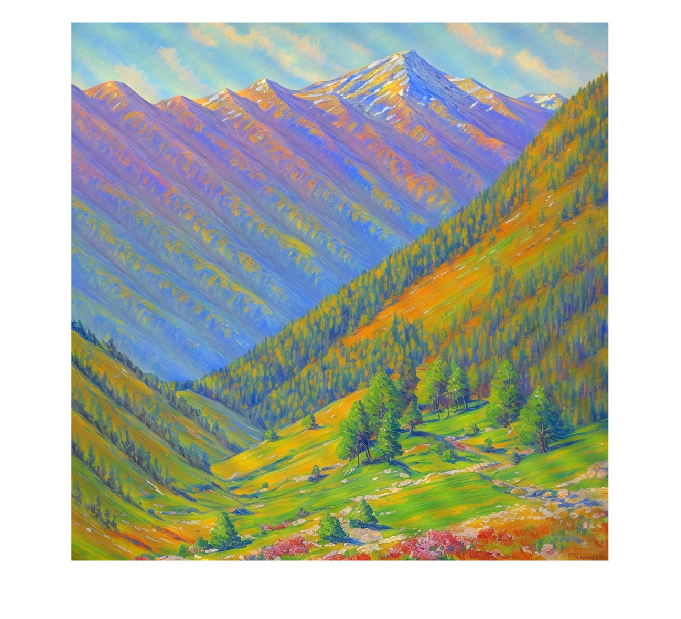

% restore image and save to the Dir
new_module = exp(new_image_fourier * log(1 + max(abs(image_fourier(:))))); 
filtered_image = real(ifft2(ifftshift(new_module .* exp(1i*arg))));
imshow(filtered_image)

imwrite(filtered_image, dir + 'filtered_image.png');